# COVID Analysis for the USA

This document explores the 2020 impact of COVID in the US in terms of excess mortality (as is defined [here](https://www.cdc.gov/nchs/nvss/vsrr/covid19/excess_deaths.htm)), total deaths of all causes, and COVID coded cases and deaths.

This file is mostly the work of Jos Martin, you can see his original post on MATLAB Central [here](https://blogs.mathworks.com/loren/2020/09/16/excess-mortality-analysis-for-the-usa/).

## Getting the Excess Deaths Data

Download excess deaths data as a table.

t = webread('https://data.cdc.gov/api/views/xkkf-xrst/rows.csv');

To help plot the data on a [geobubble](https://www.mathworks.com/help/matlab/ref/geobubble.html) chart it is useful to have another table that has the names of states (and other locations like "New York City" found in the above data) along with a Latitude and Longitude for that location

locations = webread("https://blogs.mathworks.com/images/loren/2020/stateLocation.csv");

We ONLY want to look at the `"All Causes"` data (as there are other partitions of the data in this CSV file) and we want all the data to be weighted to predicted values (since the recent data often lacks reported deaths since it takes time to get that data to the CDC - see [technical note](https://www.cdc.gov/nchs/nvss/vsrr/covid19/excess_deaths.htm) on the CDC site).  

Convert `Type`, `State` and `Outcome` to categorical as this simplifies much of the following code which sub-selects and joins on these variables. Convert `ExceedsThreshold` to a logical as this is easier to deal with that a set of different strings.

t.Type      = categorical(t.Type);
t.Outcome   = categorical(t.Outcome);
t.State     = categorical(t.State);

t.ExceedsThreshold = strcmp(t.ExceedsThreshold, 'true');

Also convert `State` in the `locations` variable to a categorical as we are going to use it in conjunction with `State` in the main table later on.

locations.State = categorical(locations.State);

Select the data we want (`All causes` and `Predicted (weighted)`) and remove the general `State == "United States"` which is the amalgamated data for all the states

t = t(t.Type == "Predicted (weighted)" & t.Outcome == "All causes" & t.State ~= "United States", :);

Get a time range covering all the data for later use

timeRange = unique(t.WeekEndingDate);

## What's Happening in a certain state?

Sub-select the data using the `State` variable (you can change this to any state you prefer to see what is happening in that state)

m = t(t.State == "Rhode Island", :)

m = 202×17 table
    WeekEndingDate       State        ObservedNumber    UpperBoundThreshold    ExceedsThreshold    AverageExpectedCount    ExcessLowerEstimate    ExcessHigherEstimate    Year    TotalExcessLowerEstimateIn2020    TotalExcessHigherEstimateIn2020    PercentExcessLowerEstimate    PercentExcessHigherEstimate            Type             Outcome      Suppress    Note
    ______________    ____________    ______________    ___________________    ________________    ____________________    ___________________    ____________________    ____    

Plot both the observed number of deaths over the time period, along with the upper bound threshold which represents the expected number of deaths plus several standard deviations of the distribution. Where the number of deaths is significantly more than the upper bound there is significantly more excess mortality than expected.

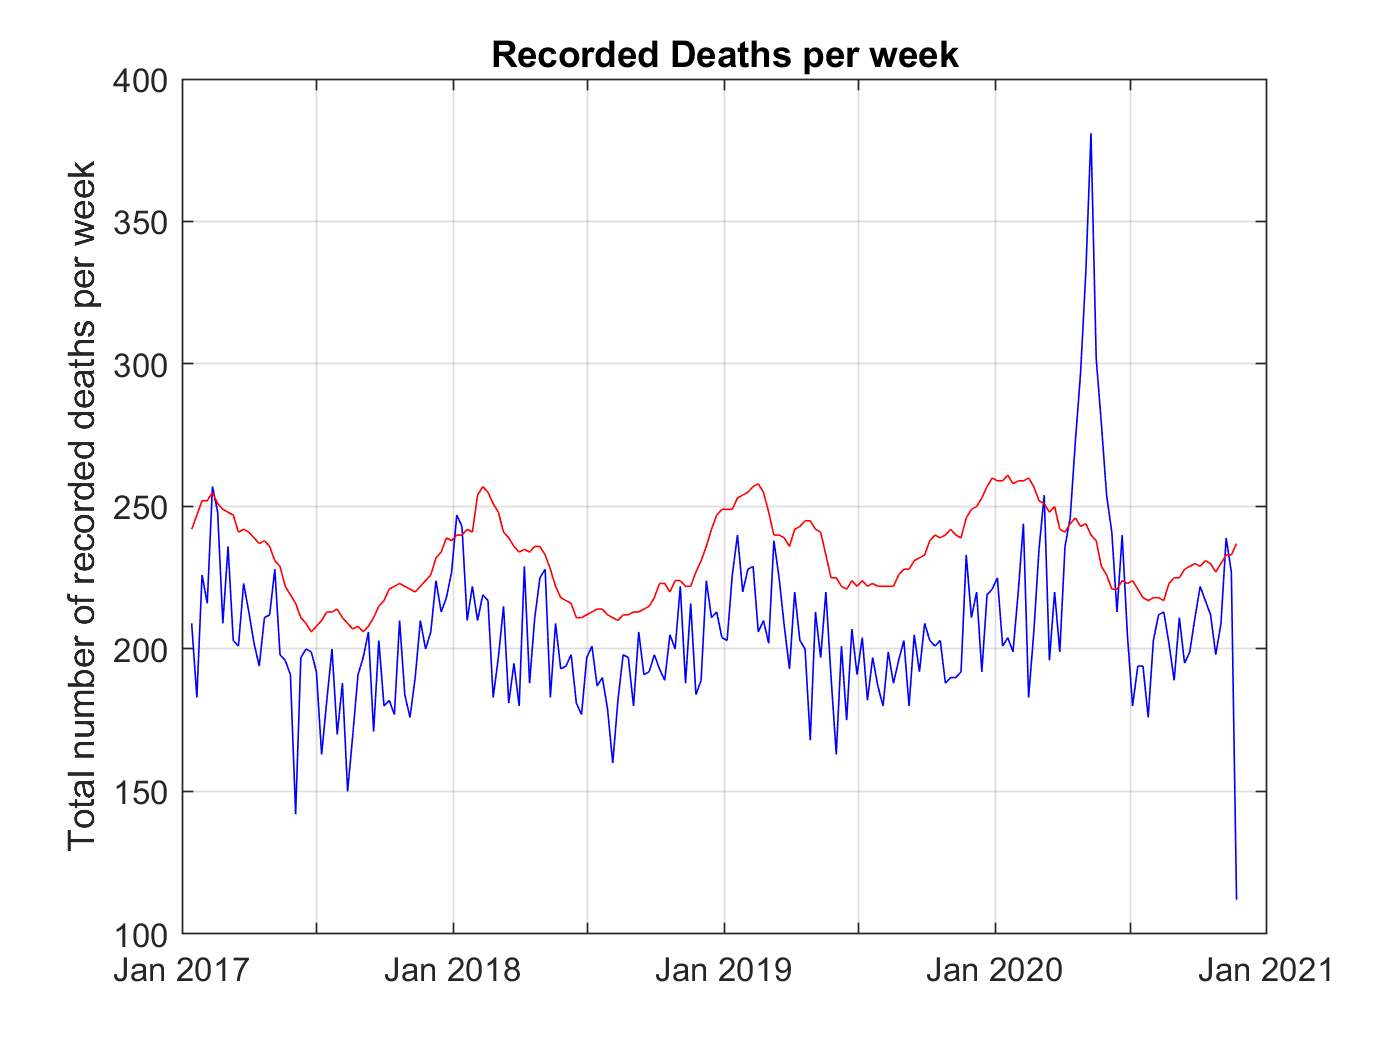

plot(timeRange, m.ObservedNumber, 'b');
hold on
plot(timeRange, m.UpperBoundThreshold, 'r')
grid on
title 'Recorded Deaths per week'
ylabel 'Total number of recorded deaths per week'
hold off

## How About the Whole of the USA?

What does the same data look like if plotted across the whole of the USA? Whilst we removed the aggregate numbers from the table earlier we can easily reproduce them by grouping the data by its date and summing across all the states. Use [findgroups](https://uk.mathworks.com/help/matlab/ref/findgroups.html) based on the `WeekEndingDate` to define the groups of data that all have the same week ending date so that [splitapply](https://uk.mathworks.com/help/matlab/ref/splitapply.html) on these groups can sum all the numbers for all states in each group to get the correct aggregate numbers.

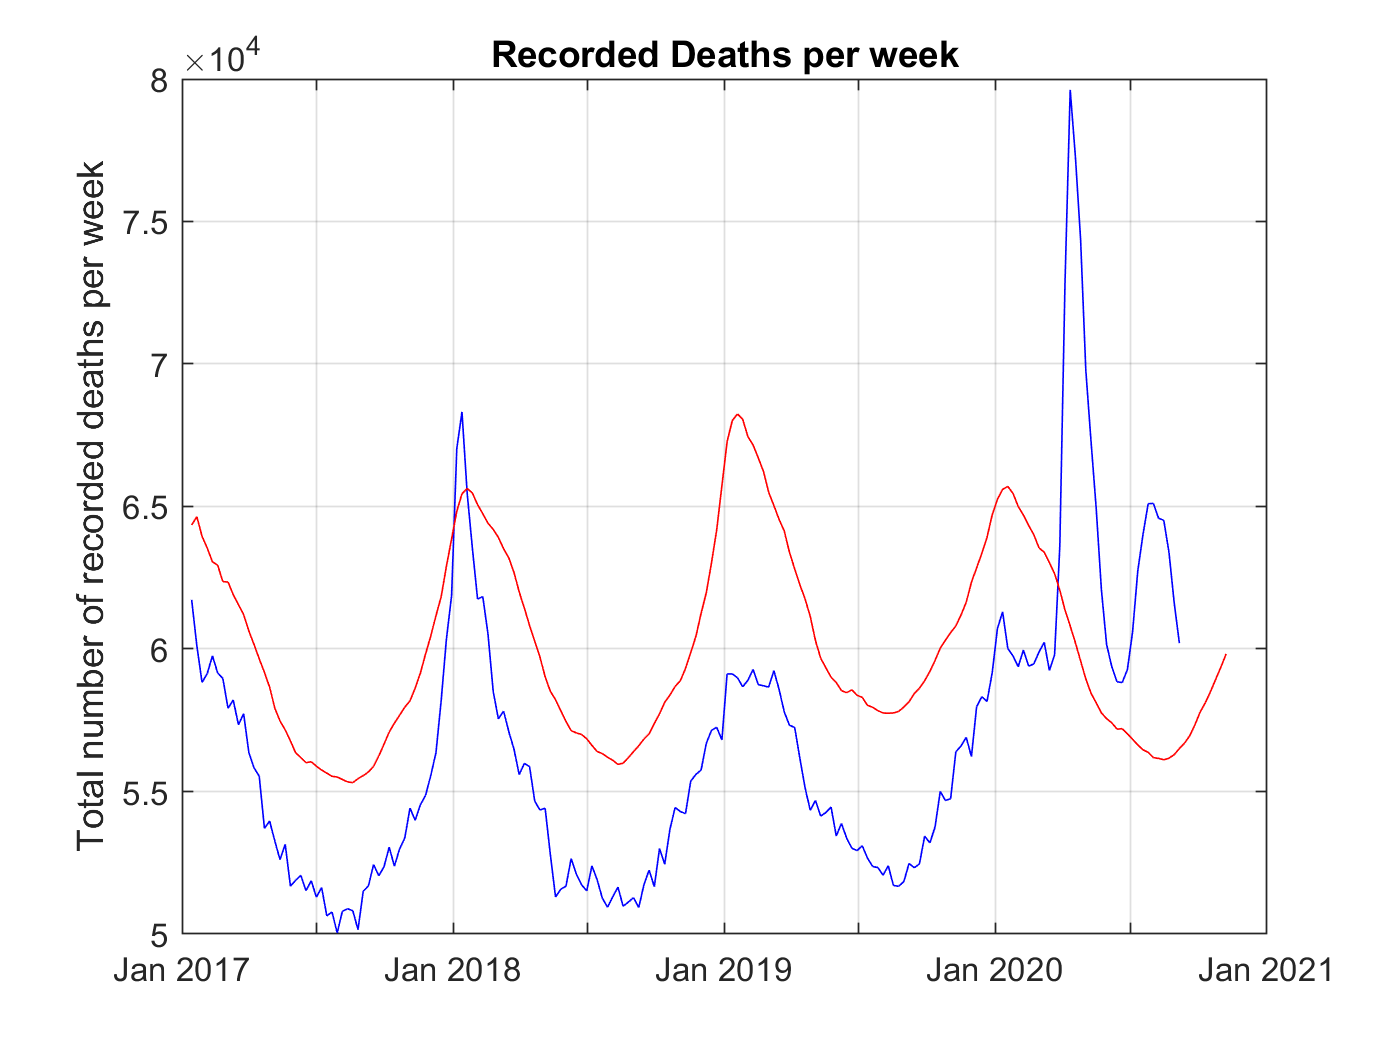

G = findgroups(t.WeekEndingDate);
plot(timeRange, splitapply(@sum, t.ObservedNumber, G), 'b')
hold on
plot(timeRange, splitapply(@sum, t.UpperBoundThreshold, G), 'r')
grid on
title 'Recorded Deaths per week'
ylabel 'Total number of recorded deaths per week'
hold off

[*Mid Sept 2020 comment*] Note the significant spike during [winter 2017 - 2018 flu season](https://en.wikipedia.org/wiki/2017%E2%80%932018_United_States_flu_season). In addition it appears that across the whole of the USA excess mortality doesn't seem to returned under the upper threshold, is running about 8,000 per week higher than expected for this time of year, and appears to be on an upward trend.

## How Many States are Exceeding their Upper Bound?

Given that we know at any given time if a State is exceeding its threshold we can easily plot the number of states that exceed their upper bound for the time range.

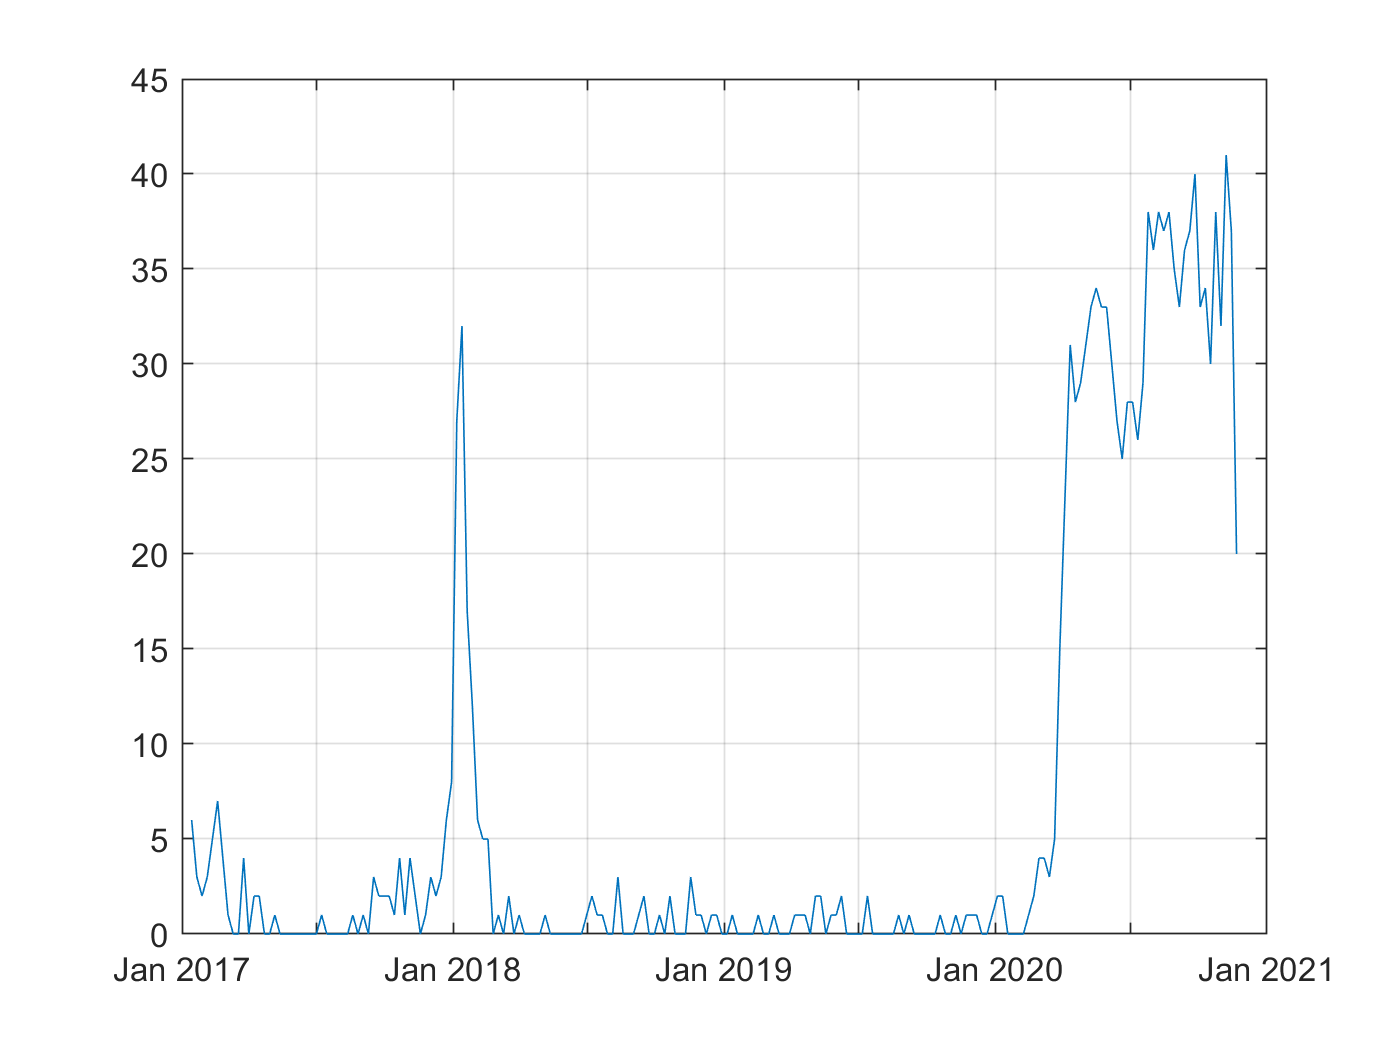

plot(timeRange, splitapply(@sum, t.ExceedsThreshold, G));
grid on

Again note the significant jump in the flu season for 2017-2018, and that currently about 30 states are still above their upper bound. But this is just an aggregate number, it might be interesting to see which states are currently above their bound and to see the evolution of the pandemic across the continental USA over time by tracking which states exceeded their bound at a given point in time.

## Which States are Exceeding their Upper Bound?

To look at which states are exceeding their upper bound (and by how much) we need to look at a point in time. We will measure this as a number of weeks since the latest data were recorded. We can then sub-select all the data so that we only have a particular week to analyse. Move the slider below to see what happens week by week across the US

weeksAgo = 1;
X = t(t.WeekEndingDate == timeRange(end-weeksAgo), :);

Use the `location` table joined with the data on `State` so that we now have the Latitude and Longitude of the States on our geobubble chart

% Join tables
X = outerjoin(X,locations,'Type','left','Keys',{'State'});

The bubble size should be normalized by the expected number of deaths in a given state. So compute the excess mortality (Observed - upper bound) and divide by something like the standard deviation (upper bound minus expected). This number is essentially the number of standard deviations from the expected for that State.

X.BubbleSize = max((X.ObservedNumber - X.UpperBoundThreshold)./(X.UpperBoundThreshold-X.AverageExpectedCount), 0);

Convert `ExceedsThreshold` to a categorical so that it can label the geobubble chart

X.ExceedsThreshold = categorical(X.ExceedsThreshold);
X = X(X.ExceedsThreshold == "true", :);
geobubble(X, "Latitude", "Longtitude", ...
    "Basemap","darkwater", ...
    "SizeVariable", "BubbleSize", ...
    "ColorVariable", "ExceedsThreshold", ...
    "MapLayout", "normal", ...
    "SizeLimits", [0 10]);

And set the plot limits to roughly the edges of the continental USA.

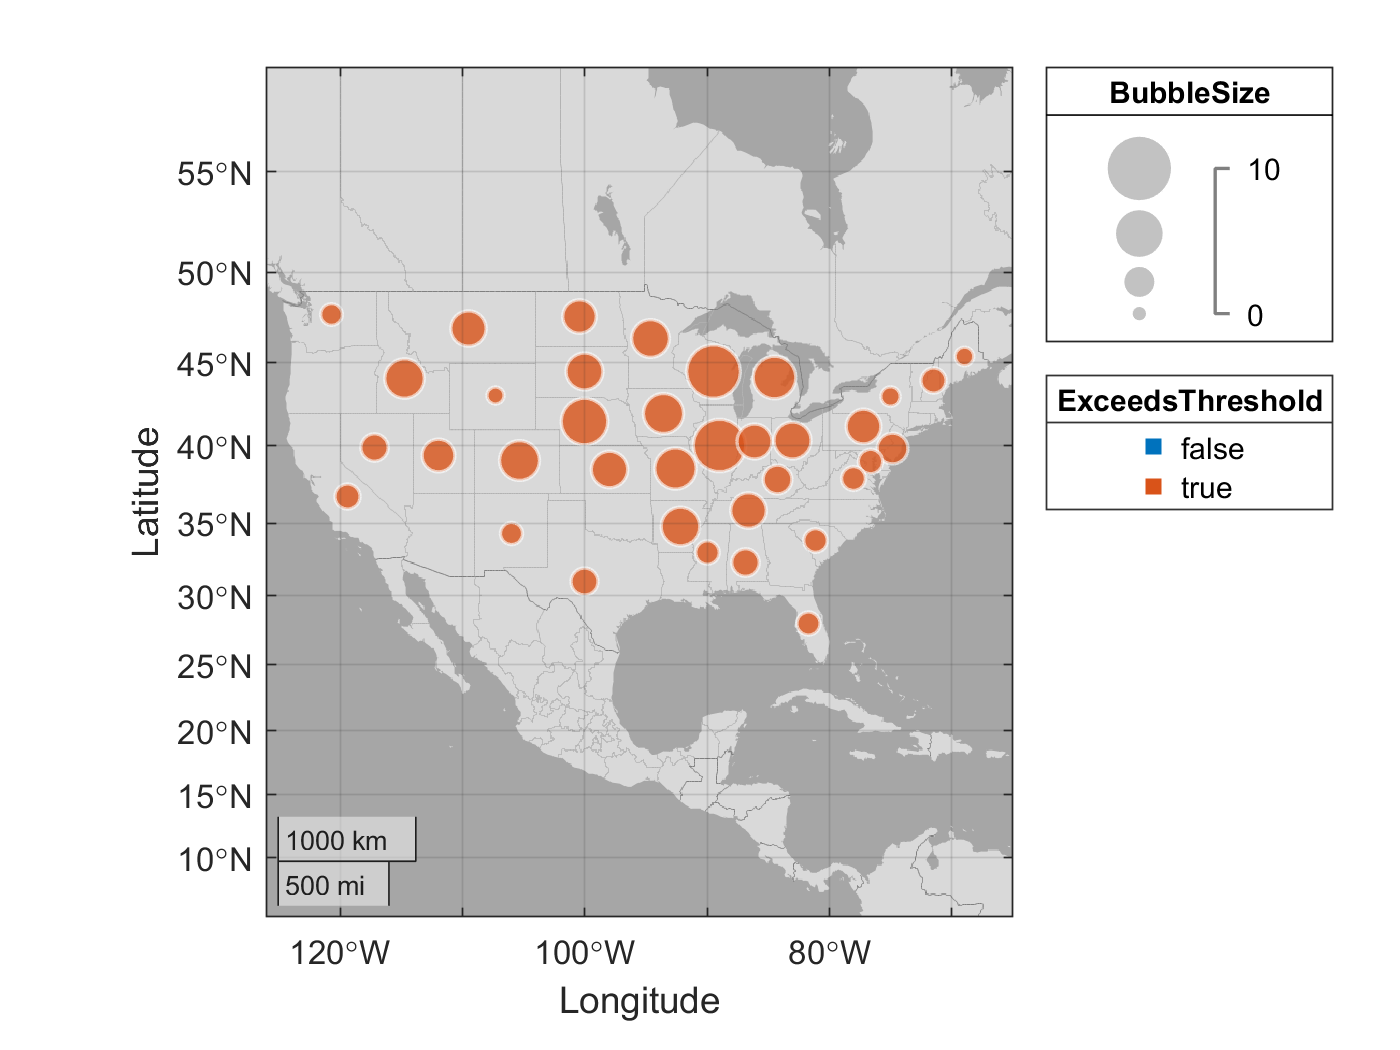

geolimits([20 51],[-126 -65])

This plot shows which states are exceeding their expected threshold and the size of the bubble indicates (in a population normalized way) by how much they are over. By changing the slider above (i.e. changing the week you are looking at) you can investigate the evolution of the pandemic across the states, watching its evolution mostly from the east coast at the beginning of the pandemic to the southern states more recently.

## Cumulative Excess Deaths

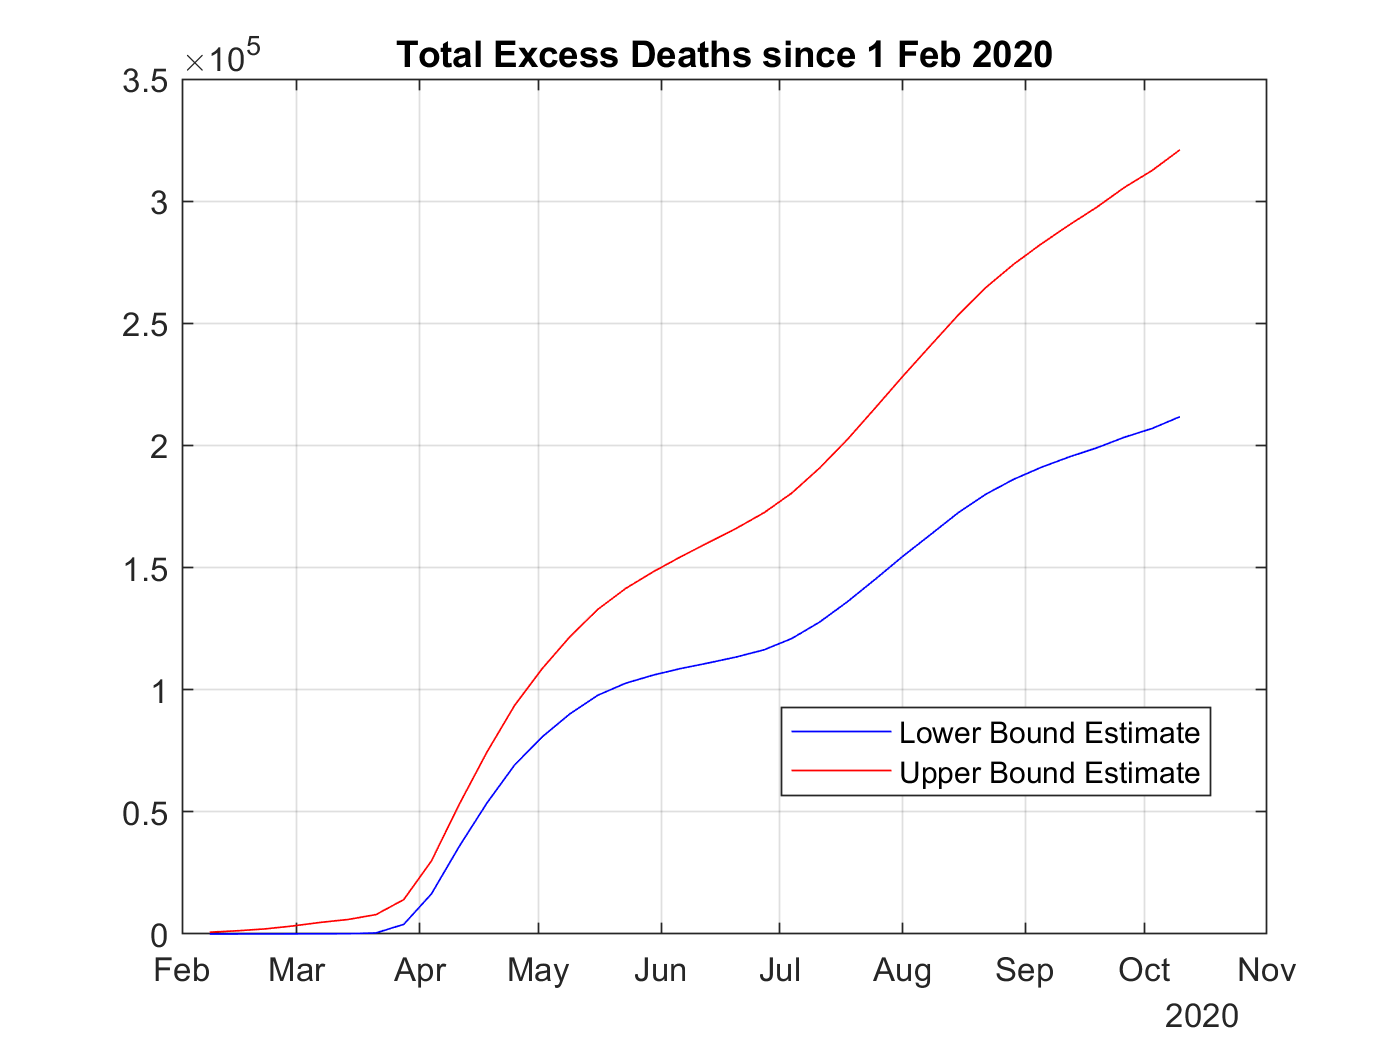

 R = t(t.WeekEndingDate > datetime('1-Feb-2020'), :);
 x = unique(R.WeekEndingDate);
 G = findgroups(R.WeekEndingDate);
 plot(x, cumsum(splitapply(@sum, R.ExcessLowerEstimate, G)), 'b')
 hold on
 plot(x, cumsum(splitapply(@sum, R.ExcessHigherEstimate, G)), 'r')
 grid on
 title("Total Excess Deaths since 1 Feb 2020")
 legend(["Lower Bound Estimate" "Upper Bound Estimate"], "Location", "best")
 hold off

## Weekly Deaths By Year

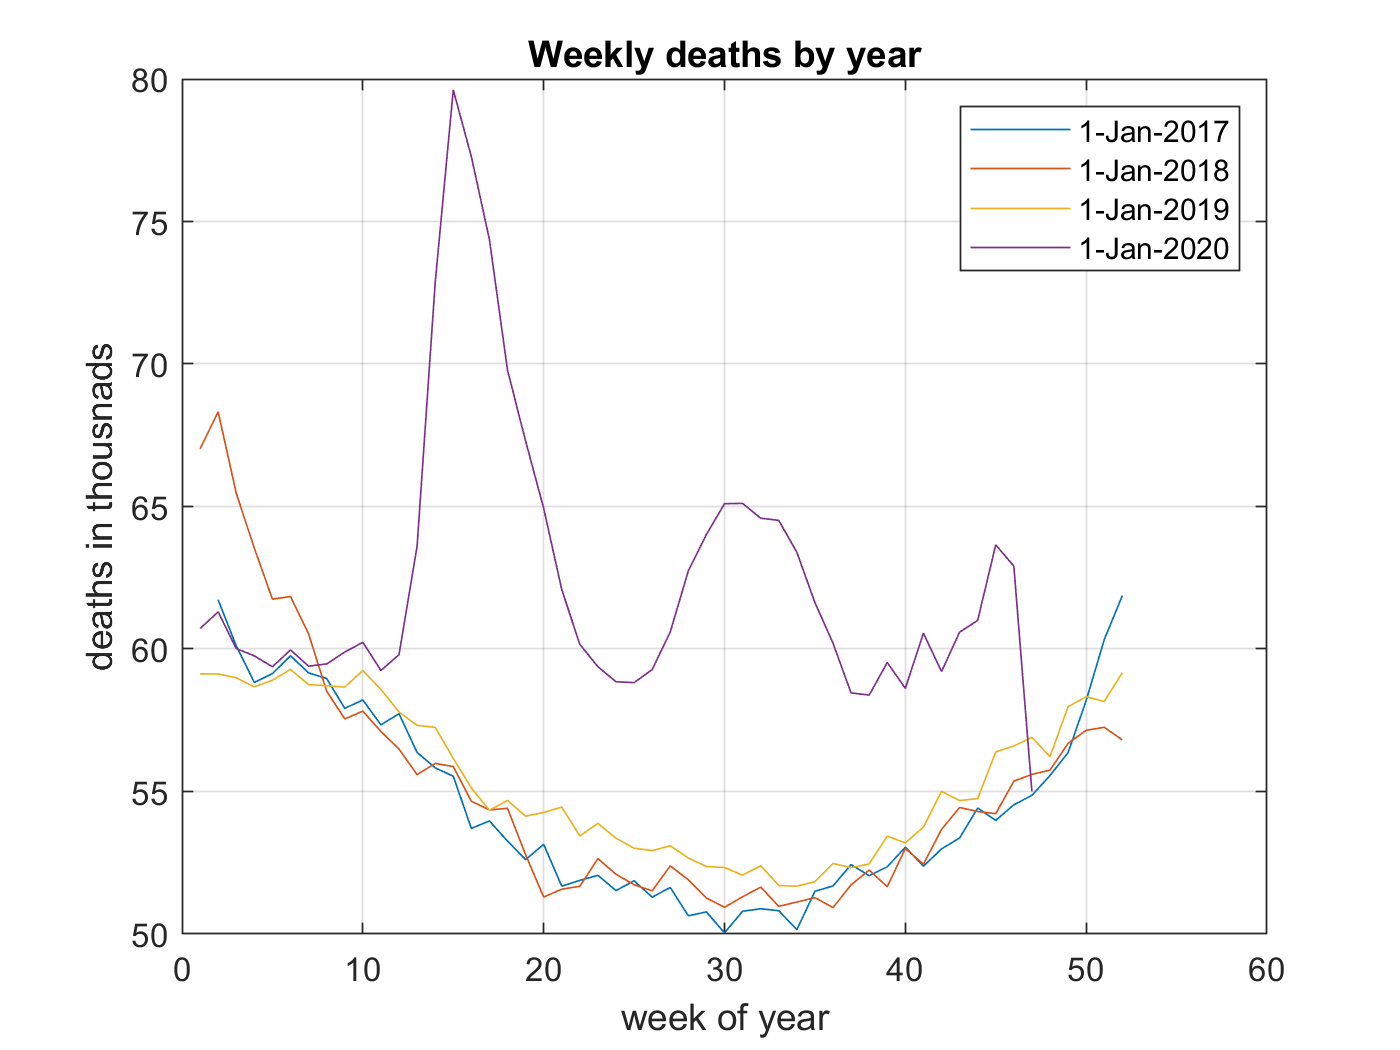

 dtvec = [];
 for n=2017:2021
     dtvec{end+1} = ['1-Jan-' num2str(n)];
 end
 
 for n=1:length(dtvec)-1
     R = t(t.WeekEndingDate >= datetime(dtvec{n}), :);
     R = R(R.WeekEndingDate < datetime(dtvec{n+1}), :);
     R = R(~isnan(R.ObservedNumber), :);
     x = unique(R.WeekEndingDate);
     G = findgroups(R.WeekEndingDate);
     plot(week(x), splitapply(@sum, R.ObservedNumber, G)./1000)
     hold all     
 end
 grid on
 title("Weekly deaths by year")
 xlabel('week of year')
 ylabel('deaths in thousnads')
 legend(dtvec(1:n));
 hold off

## Cumulitive Deaths By Year

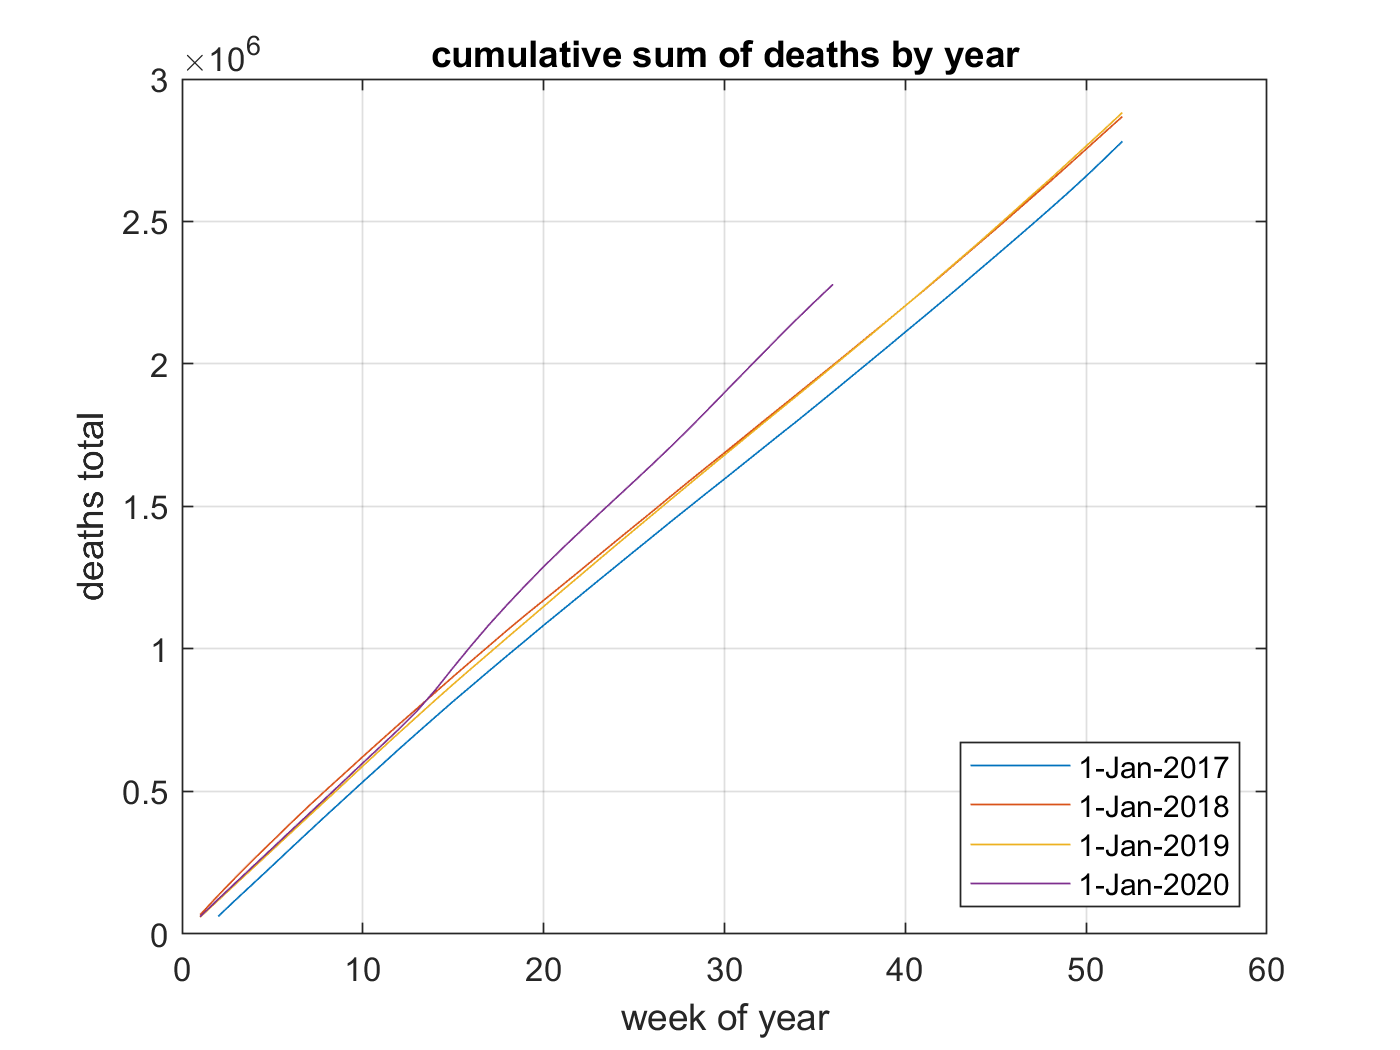

 dtvec = [];
 for n=2017:2021
     dtvec{end+1} = ['1-Jan-' num2str(n)];
 end
 
 for n=1:length(dtvec)-1
     R = t(t.WeekEndingDate >= datetime(dtvec{n}), :);
     R = R(R.WeekEndingDate < datetime(dtvec{n+1}), :);
     x = unique(R.WeekEndingDate);
     G = findgroups(R.WeekEndingDate);
     plot(week(x), cumsum(splitapply(@sum, R.ObservedNumber, G)))
     hold all     
 end
 grid on
 title("cumulative sum of deaths by year")
 xlabel('week of year')
 ylabel('deaths total')
 legend(dtvec(1:n), 'Location', 'southeast');
 hold off

## Covid Deaths by Age

In this section we download a different data set that uses only COVID coded deaths.  This data set contains a breakdown by age, sex, and week.

%https://data.cdc.gov/NCHS/Provisional-COVID-19-Death-Counts-by-Sex-Age-and-W/vsak-wrfu
t2 = webread('https://data.cdc.gov/api/views/vsak-wrfu/rows.csv');

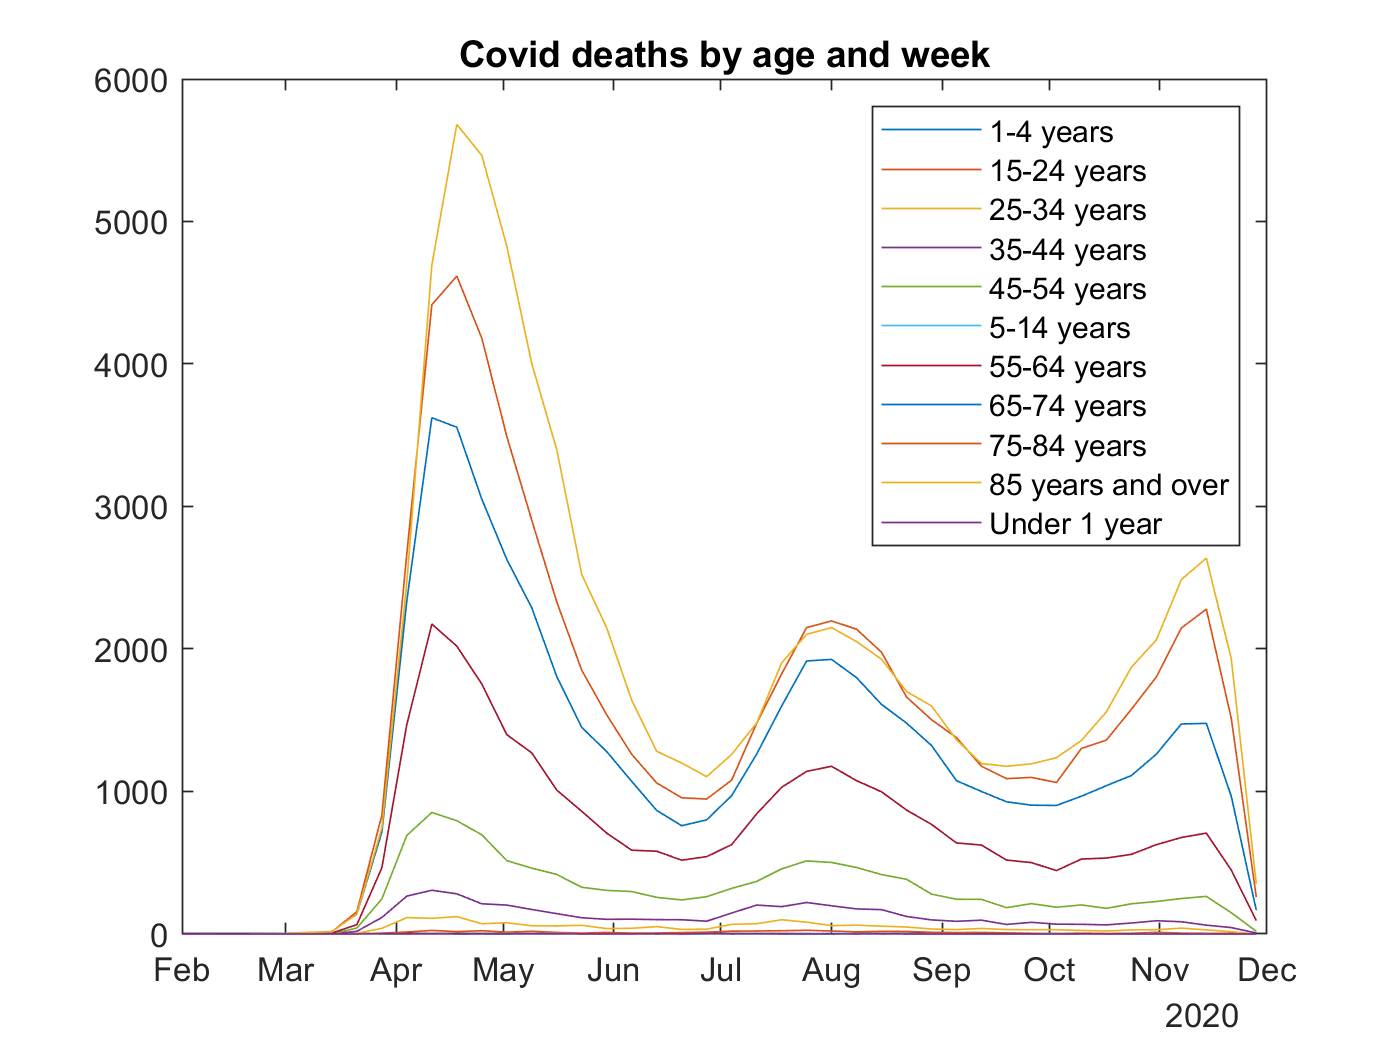

t2.Sex      = categorical(t2.Sex);
t2.AgeGroup      = categorical(t2.AgeGroup);
t2 = t2(t2.AgeGroup ~= "All Ages" & t2.Sex ~= "Male" & t2.Sex ~= "Female",:);
timeRange2 = unique(t2.EndWeek);
agerange = unique(t2.AgeGroup);

G = findgroups(t2.EndWeek);

for n=1:length(agerange)
    plot(timeRange2, t2(t2.AgeGroup == agerange(n),:).COVID_19Deaths);
    hold all;
end
legend(cellstr(agerange))
title('Covid deaths by age and week')
hold off;

## COVID New Cases, Deaths and Rough Mortality Trend

In this section we download a dataset for New Deaths and New Cases by day and state.

t3 = webread('https://data.cdc.gov/api/views/9mfq-cb36/rows.csv');
t3.state = categorical(t3.state);
timeRange3 = unique(t3.submission_date);
G = findgroups(t3.submission_date);

Let's look at the new cases and deaths, by day, for the entire US.

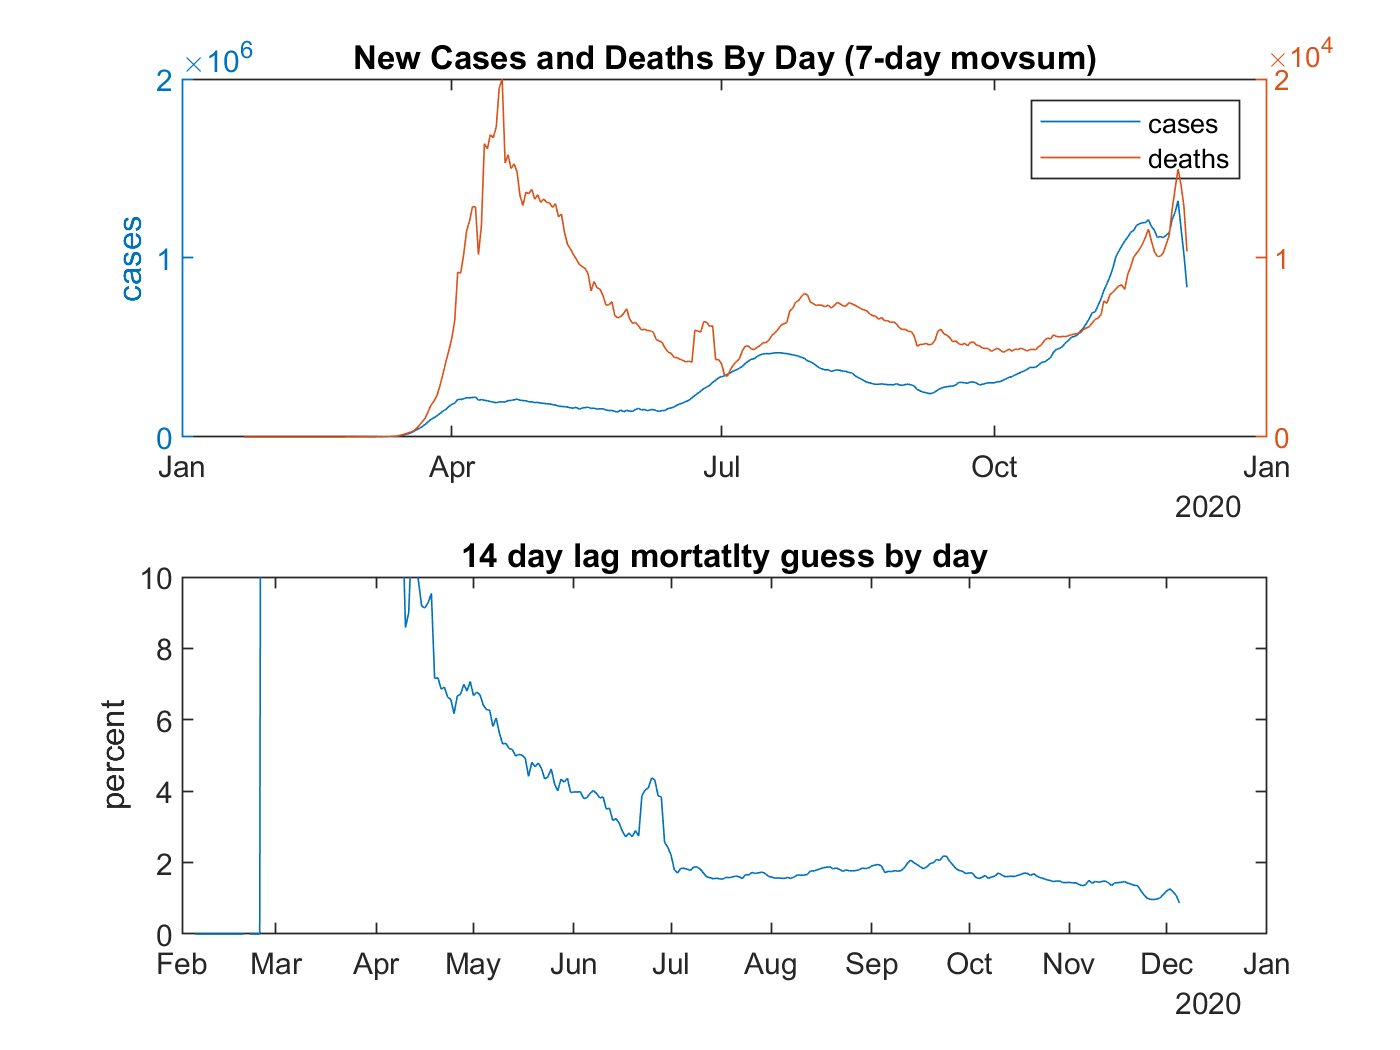

[h1a, h2a] = case_death_mort(G, timeRange3, t3);

Lets look at the same plots, but for just one state.

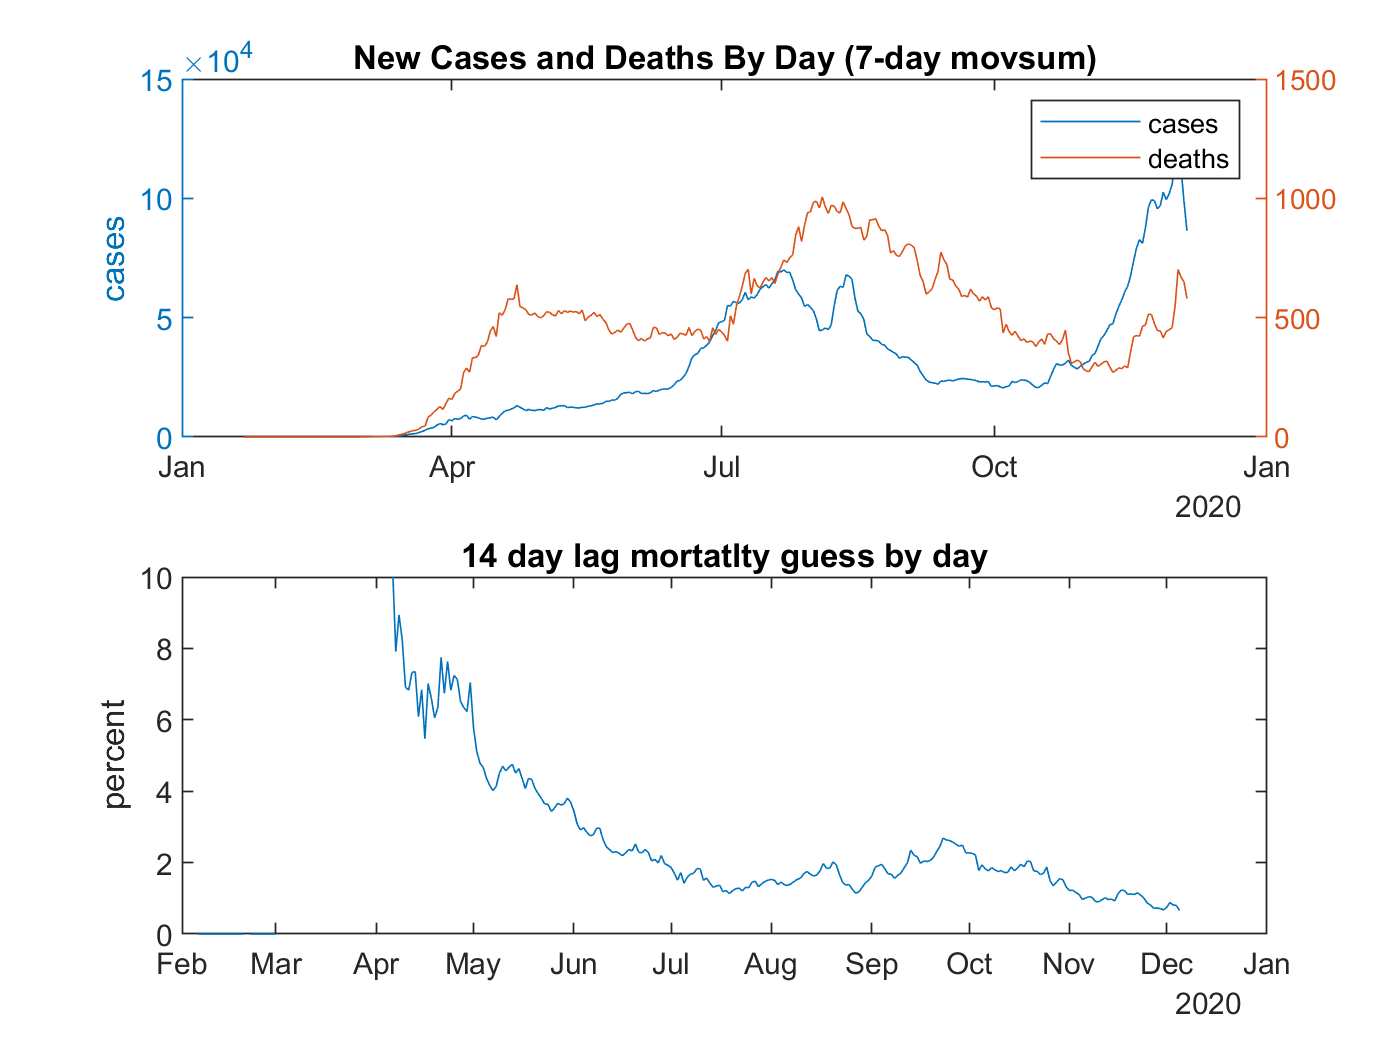

state_of_interst = 'CA';
t_state = t3(t3.state == state_of_interst, :);
G = findgroups(t_state.submission_date);
[h1b, h2b] = case_death_mort(G, timeRange3, t_state);

Let's extract the mortality numbers from each chart and make new chart showing both.  If the mortality was primiarly driven by 'vulnerable' individuals dieing early we should expect to see a different shape mortality curve for a later hit state as compared to the US total.

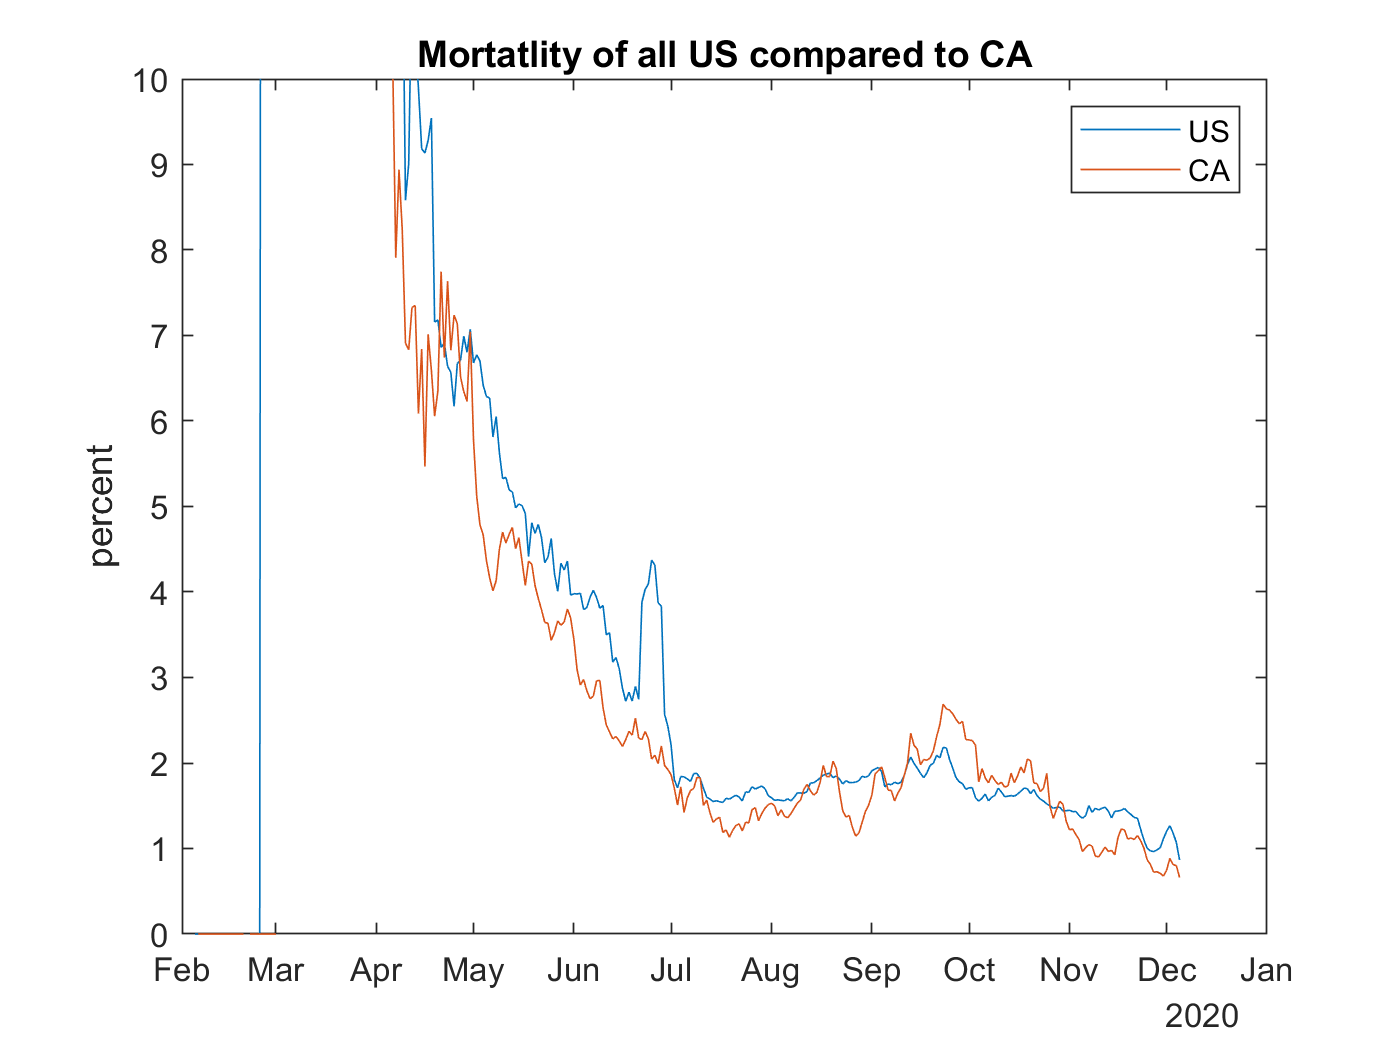

figure;
d = h2b.XData;
mort_us = h2a.YData;
mort_state = h2b.YData;
plot(d, mort_us, d, mort_state);
ylim([0 10]);
ylabel('percent');
title(['Mortatlity of all US compared to ' state_of_interst ])
legend('US', state_of_interst);

## Misc Functions

function [h1,h2] = case_death_mort(G, timerange, tt)

% anonymous function for delays a vector
shift = @(data, delay) [zeros(delay,1); data(1:end-delay)];

figure;
subplot(211);
h1 = plotyy(timerange, movsum(splitapply(@sum, tt.new_case, G), 7), ...
       timerange, movsum(splitapply(@sum, tt.new_death, G), 7) ...
       );
ylabel('cases');
title('New Cases and Deaths By Day (7-day movsum)');
legend('cases', 'deaths');

subplot(212);
h2 = plot(timerange, ...
    100 * ...
    movsum(splitapply(@sum, tt.new_death, G), 7) ./ ...
    shift(movsum(splitapply(@sum, tt.new_case, G), 7), 14) ...
    );
ylim([0 10])
ylabel('percent');
title('14 day lag mortatlty guess by day')
end

